#  Icy moon with non-rigid core and lateral variations 

In this notebook the tidal response of an icy moon (**nonrigid core+ocean+ice shell**) with lateral variations is computed

clearvars
clc
set(0,'defaulttextInterpreter','latex') 
mfile_name          = mfilename('fullpath');
if contains(mfile_name,'LiveEditorEvaluationHelper')
    mfile_name=matlab.desktop.editor.getActiveFilename;
end
[pathstr,name,ext]  = fileparts(mfile_name);
cd(pathstr);
cd('..')
addpath(genpath(pwd))

## Interior model

The Europa interior model of [Beuthe et al. 2013](https://www.sciencedirect.com/science/article/pii/S0019103512004745?casa_token=xg0XfpmaHT4AAAAA:Qau6ppdURvhX_Vgm_NiDZVwEtERNnqcosVviHYGaLIHJLBugG7ZgBEnHNPG921Qc5SZAktQ6kw) is considered with added lateral variations. Note that the model is assumed to be elastic & incomressible. 

% MEAN VALUES 
% elastic Europa 
%Core layer (1)
Interior_Model_Uni(1).R0= 587; 
Interior_Model_Uni(1).rho0= 5500;  
%Silicate layer (2) 
Interior_Model_Uni(2).R0= 587+840; 
Interior_Model_Uni(2).rho0= 3500; 
Interior_Model_Uni(2).mu0=70E9; 
% Ocean layer (3) 
Interior_Model_Uni(3).R0=587+840+114; 
Interior_Model_Uni(3).rho0= 1000; 
Interior_Model_Uni(3).ocean=1; 
%Ice layer (4)
Interior_Model_Uni(4).R0= 587+840+114+12+8;  
Interior_Model_Uni(4).rho0=920; 
Interior_Model_Uni(4).mu0=3.3E9;  
omega0=2.048E-5;
% Lateral Variations, provided in peak to peak variations  
Interior_Model=Interior_Model_Uni; 
Interior_Model(2).mu_variable_p2p=[2 0 10];

## Define forcing

The forcing potential is defined

Forcing(1).Td=2*pi/omega0; 
Forcing(1).n=2; 
Forcing(1).m=0; 
Forcing(1).F=1;

## Define numerics used to compute the tidal response 

%radial discretization
Numerics.Nlayers = length(Interior_Model); % number of concentric layers. Including the core!
Numerics.method = 'variable'; % method of setting the radial points per layer
Numerics.Nrbase = 200;
%code parallelization
Numerics.parallel_sol = 0; % Use a parfor-loop to call get_Love, either 0 or 1
Numerics.parallel_gen = 0; % Calculate potential coupling files and the propagation inside get_solution using parfor-loops, either 0 or 1
Numerics.perturbation_order = 2;
[Numerics, Interior_Model] = set_boundary_indices(Numerics, Interior_Model,'verbose');

Inside set_boundary_indices: 
Nrlayer: 0  200  200  200
BCindices: 201  401  601
Nr: 600
 


Numerics.solution_cutoff = 12; % maximum degree of solution, not used if perturbation order is specified
Numerics.load_couplings = 1; % 0=no loading, 1=loading of specific file, 2=searches for big enough file
Numerics.Nenergy = 12; % maximum degree to which energy dissipation is expanded 
Numerics.rheology_cutoff = 2; % maximum order of difference (so in log) up to which rheology is still used 
Numerics.coupling_file_location = 'files/couplings/'; % MUST END WITH A '/' , Location where coupling files are saved or should be saved 


## Compute the tidal response using LOV3D

Compute Tidal Response using LOV3D for the set of interior models specified 

% get the Love numbers for the spherically-symmetric model
Interior_Model_Uni_U = get_rheology(Interior_Model_Uni,Numerics,Forcing);

Viscosity for layer 2 not provided, I will assume the layer is elastic 
Bulk modulus for layer 2 not provided, I will assume the layer is incompressible 
No lateral variations provided for layer 2, I will assume the layer is spherically-symmetric 
Viscosity for layer 3 not provided, I will assume the layer is elastic 
Bulk modulus for layer 3 not provided, I will assume the layer is incompressible 
Layer 3 is an ocean layer 
No lateral variations provided for layer 3, I will assume the layer is spherically-symmetric 
Viscosity for layer 4 not provided, I will assume the layer is elastic 
Bulk modulus for layer 4 not provided, I will assume the layer is incompressible 
No lateral variations provided for layer 4, I will assume the layer is spherically-symmetric 


[Love_Spectra_Uni,y_rad_Uni]=get_Love(Interior_Model_Uni_U,Forcing,Numerics,'verbose');

Obtaining Couplings....
Only uniform layers so coupling matrix is zero
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    5.87000e+02    5.50000e+03    0    -
2    1.42700e+03    3.50000e+03    7.00000e+10    3.30000e+16 
3    1.54100e+03    1.00000e+03        3.30000e+16 
4    1.56100e+03    9.20000e+02    3.30000e+09    3.30000e+16 
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.37604    5.9783    0    -
2    0.91416    3.8043    21.2121    10000000 NaN
3    0.98719    1.087        10000000 NaN
4    1    1    1    10000000 NaN
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
4    (0,0)   0.00000e+00
Bulk Modulus
Layer#      (n,m)  

iforcing=find(Love_Spectra_Uni.n==Forcing.n & Love_Spectra_Uni.m==Forcing.m);
k2_uniform=Love_Spectra_Uni.k(iforcing); 
h2_uniform=Love_Spectra_Uni.h(iforcing);
% get the Love numbers for the model with lateral variations 
Interior_Model_U = get_rheology(Interior_Model,Numerics,Forcing);

Viscosity for layer 2 not provided, I will assume the layer is elastic 
Bulk modulus for layer 2 not provided, I will assume the layer is incompressible 
Viscosity for layer 3 not provided, I will assume the layer is elastic 
Bulk modulus for layer 3 not provided, I will assume the layer is incompressible 
Layer 3 is an ocean layer 
No lateral variations provided for layer 3, I will assume the layer is spherically-symmetric 
Viscosity for layer 4 not provided, I will assume the layer is elastic 
Bulk modulus for layer 4 not provided, I will assume the layer is incompressible 
No lateral variations provided for layer 4, I will assume the layer is spherically-symmetric 


[Love_Spectra,y_rad]=get_Love(Interior_Model_U,Forcing,Numerics,'verbose');

Obtaining Couplings....
 Couplings Loaded from: files/couplings/L_struct__Nrheomax__2__forc__2_0_per2.mat
Loading coupling file took: 0.083234 seconds
------------- INTERIOR MODEL ----------- 
AVERAGE PROPERTIES (dimensional)
Layer#     R[m]    rho[kg.m^{-3}]    mu[Pa]    K[Pa]    eta[Pa.s]
1    5.87000e+02    5.50000e+03    0    -
2    1.42700e+03    3.50000e+03    7.00000e+10    3.30000e+16 
3    1.54100e+03    1.00000e+03        3.30000e+16 
4    1.56100e+03    9.20000e+02    3.30000e+09    3.30000e+16 
AVERAGE PROPERTIES (non-dimensional)
Layer#     R[-]    rho[-]    mu[-]    K [-]     eta[-]
1    0.37604    5.9783    0    -
2    0.91416    3.8043    21.2121    10000000 NaN
3    0.98719    1.087        10000000 NaN
4    1    1    1    10000000 NaN
RHEOLOGY  VARIATIONS
Shear Modulus
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
2    (2,0)   2.98248e-02
Layer#      (n,m)           amplitude[mu_n^m/mu_0^0]
3    (0,0)   0.00000e+00
Layer#      (n,m)           am

## Plot the y functions 

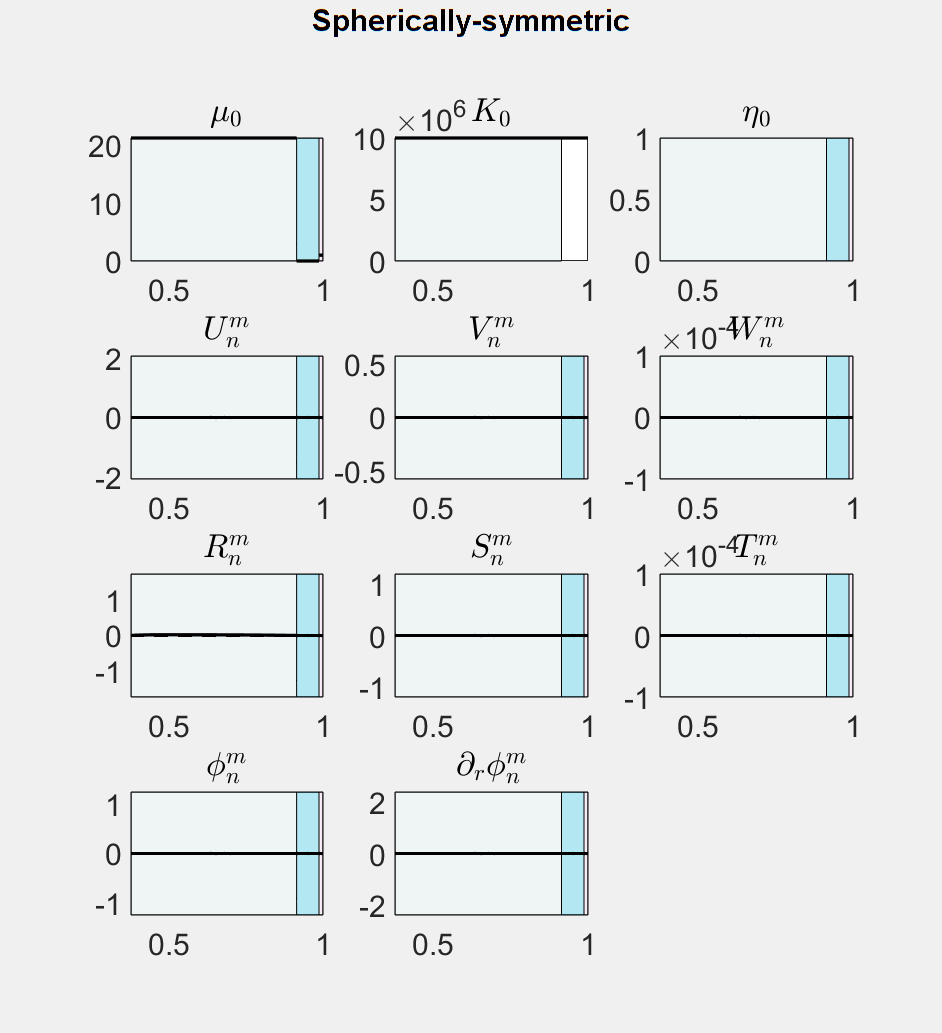

% Plot solution of the spherically-symmetric model
plot_y(Interior_Model_Uni_U,y_rad_Uni)

% Plot solution of the model with lateral variations
plot_y(Interior_Model_U,y_rad)